# 技巧合集

## 实时脚本控件

滑块

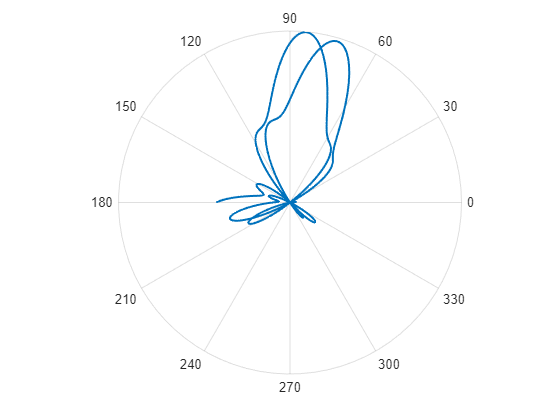

a=-3.2;
clc;cla;clf
x=linspace(0,2*pi,500);
hdl=polarplot(x,sin(x)+sin(a.*x).^3,'LineWidth',1.5);
ax=gca;ax.RTick=[];

下拉列表

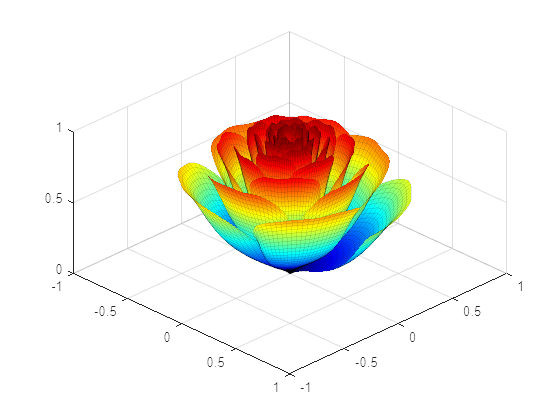

clc;cla;clf
CMAP="jet";
[x,t]=meshgrid((0:24)./24,(0:0.5:575)./575.*20.*pi+4*pi);
p=(pi/2)*exp(-t./(8*pi));
change=sin(15*t)/150;
u=1-(1-mod(3.6*t,2*pi)./pi).^4./2+change;
y=2*(x.^2-x).^2.*sin(p);
r=u.*(x.*sin(p)+y.*cos(p));
h=u.*(x.*cos(p)-y.*sin(p));
surface(r.*cos(t),r.*sin(t),h,'EdgeAlpha',0.1,...
    'EdgeColor',[0 0 0],'FaceColor','interp')
colormap(CMAP)
grid on
view(45,45)

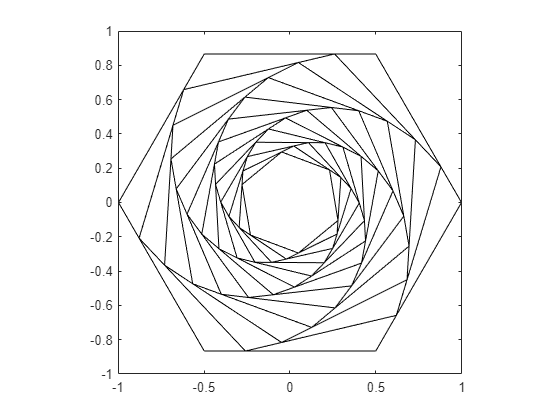

lenRatio=0.24;
numEdge=6;
numPolygon=12;

clc;cla;clf
theta=linspace(0,2*pi,numEdge+1);
X=cos(theta);X(end)=[];
Y=sin(theta);Y(end)=[];

fill(X,Y,[0,0,0],'FaceColor','none');
hold on;
axis equal
axis([-1,1,-1,1])

for i=1:numPolygon
    tX=[X(2:end),X(1)];
    tY=[Y(2:end),Y(1)];
    X=(tX-X).*lenRatio+X;
    Y=(tY-Y).*lenRatio+Y;
    fill(X,Y,[0,0,0],'FaceColor','none');
end
hold off

## 矩阵与数组

### 元素替换

假设我们要把全零矩阵第(2,3)个元素及第(3,2)个元素变为1，实现该功能需要：

A=zeros(4,4);
A(2,3)=1;
A(3,2)=1

A =      0     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     0


如果编写了如下代码：

B=zeros(4,4);
B([2,3],[3,2])=1

B =      0     0     0     0
     0     1     1     0
     0     1     1     0
     0     0     0     0


我们会发现不只改变了两个元素，但我们可以通过`sub2ind`函数将双变量索引改为单变量索引，例如([4,4]为矩阵尺寸)：

C=zeros(4,4);
C(sub2ind([4,4],[2,3],[3,2]))=1

C =      0     0     0     0
     0     0     1     0
     0     1     0     0
     0     0     0     0


### 转置与共轭转置

对于实矩阵而言'和.'没有任何区别，但是对于符号矩阵和虚数矩阵就不一样了，前者是共轭转置，后者才是转置:


A=[0,3+4i;0,0];

A1=A'

A1 =    0.0000 + 0.0000i   0.0000 + 0.0000i
   3.0000 - 4.0000i   0.0000 + 0.0000i


A2=A.'

A2 =    0.0000 + 0.0000i   0.0000 + 0.0000i
   3.0000 + 4.0000i   0.0000 + 0.0000i


### 特殊稀疏矩阵创建

构造一个100阶的稀疏矩阵A,要求非零元素有50个，且为1到50

% 10000个数里随机选不重复的50个数
pos=randperm(10000,50);
% 将线性索引转换为下标
[row,col]=ind2sub([100,100],pos);
% 稀疏矩阵创建
A=sparse(row,col,1:50)

### 含符号函数的数组的索引

这是对于知乎上一个问题的回答，原问题遇到的情况图片如下(即数组的某行某列的元素无法直接获取)：

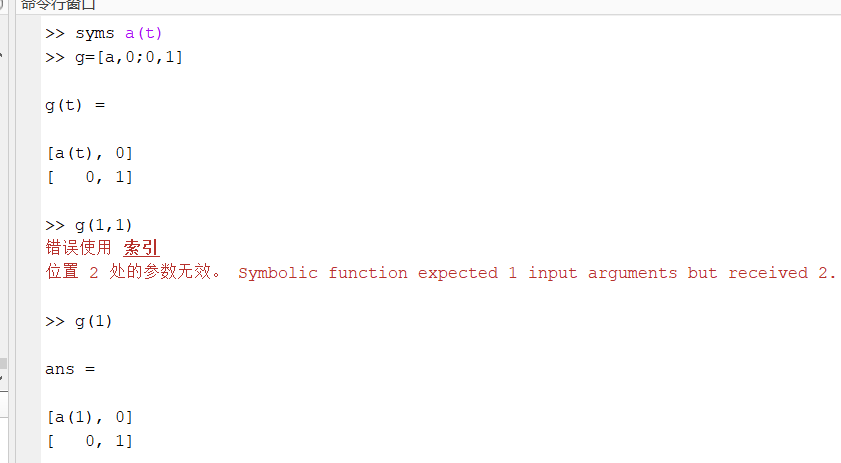

可以使用formula函数获取每个位置的对象，给个实例：


syms a(t)

g=[a,0;0,1];
gb=formula(g);
gb(1,1)

$$ans = a\left(t\right)$$

### 定义**大小为0的矩阵**

要创建一个[x1,y1;x2,y2;x3,y3;... ...]这样的矩阵，每一轮往最后加入新点，但每次加入点的个数未知，要添加次数也未知，我们就不如创建一个0xn大小的矩阵不断的往后面增添新的元素：

% 创建0行2列矩阵
P=zeros(0,2);
% 循环随机5-10之间的随机轮
for i=1:randi([5,10],[1,1]) 
    % 每次随机增加2-5行随机数
    P=[P;rand(randi([2,5],[1,1]),2)]
end

但是大小为0的矩阵不会提前分配内存

## 数据

### 删除nan值

一维向量：

oriData=[1 nan nan 4 nan 5 6]

oriData =      1   NaN   NaN     4   NaN     5     6


oriData(isnan(oriData))=[]

oriData =      1     4     5     6


删除含nan的行：

oriData=[1 2;nan 4;5 6;7 nan]

oriData =      1     2
   NaN     4
     5     6
     7   NaN


tData=sum(oriData,2);
oriData(isnan(tData),:)=[]

oriData =      1     2
     5     6


当然如果要删除含nan的列，将代码改为：

tData=sum(oriData,1);
oriData(:,isnan(tData))=[]

oriData =      1     2
     5     6


### 精度设置

一般MATLAB中如果两个数的数值相差小于eps，则认为数值相同，例如以下两个判断MATLAB都会认为是对的：

1==1+eps/2

ans = logical
   1


1==1+1e-20

ans = logical
   1


eps的数值为2.2204e-16，只要我们将精度设置的更高就不会出现上述问题，例如：

`digits用于规定运算精度即有效数字；vpa表明该运算需要控制精度`

digits(50)
logical(vpa(1)==vpa(1)+vpa(1e-20))

ans = logical
   0


再比如，我想显示圆周率的前100位小数：

digits(100)
pi100=vpa(pi)

$$pi100 = 3.141592653589793238462643383279502884197169399375105820974944592307816406286208998628034825342117068$$

### 将小数转化为分数并提取分子和分母

a=2065/2013 ;
b=split(rats(a),'/')

b = 2×1 cell 数组
    {'   2065'}
    {'2013  ' }


c=str2num(b{1})

c = 2065

d=str2num(b{2})

d = 2013

A = 3×3 cell 数组
    {[1]}    {[2]}    {[3]}
    {[4]}    {[5]}    {[6]}
    {[7]}    {[8]}    {[9]}


B1 =      1
     4
     7
     2
     5
     8
     3
     6
     9


B2 =      1     2     3
     4     5     6
     7     8     9


C = 2×2 cell 数组
    {'12'}    {'34'}
    {'56'}    {'78'}


D =     12    34
    56    78


A =      1     2     3
     4     5     6


B = 2×2 cell 数组
    {[1]}    {[2 3]}
    {[4]}    {[5 6]}


B1 = 2×3 cell 数组
    {[1]}    {[2]}    {[3]}
    {[4]}    {[5]}    {[6]}


B2 = 2×3 cell 数组
    {[1]}    {[2]}    {[3]}
    {[4]}    {[5]}    {[6]}


### 元胞与数组

#### 元胞转数值数组

将全部元素提取出来并排列成一列:

A={1,2,3;4,5,6;7,8,9}

A = 3×3 cell 数组
    {[1]}    {[2]}    {[3]}
    {[4]}    {[5]}    {[6]}
    {[7]}    {[8]}    {[9]}


% 将全部元素提取出来并排列成一列
B1=[A{:}]'

B1 =      1
     4
     7
     2
     5
     8
     3
     6
     9


将数值元胞数组转换为数值数组:

A={1,2,3;4,5,6;7,8,9};
% 将数值元胞数组转换为数值数组
B2=cell2mat(A)

B2 =      1     2     3
     4     5     6
     7     8     9


% 以下方式也可但速度较慢
% B2=reshape([A{:}],size(A))

字符串元胞转数值数组:

C={'12','34';'56','78'}

C = 2×2 cell 数组
    {'12'}    {'34'}
    {'56'}    {'78'}


D=reshape(str2num(char(C)),size(C))

D =     12    34
    56    78


#### **数值数组转元胞**

分块并转元胞

A=[1,2,3;4,5,6]

A =      1     2     3
     4     5     6


% 行分成两块每块一行
% 列分成两块分别1行和2行
B=mat2cell(A,[1,1],[1,2])

B = 2×2 cell 数组
    {[1]}    {[2 3]}
    {[4]}    {[5 6]}


不分块转元胞，以下两种方法等价，但显然第二种方法简单很多：

A=[1,2,3;4,5,6];

B1=mat2cell(A,ones(1,size(A,1)),ones(1,size(A,2)))

B1 = 2×3 cell 数组
    {[1]}    {[2]}    {[3]}
    {[4]}    {[5]}    {[6]}



B2=num2cell(A)

B2 = 2×3 cell 数组
    {[1]}    {[2]}    {[3]}
    {[4]}    {[5]}    {[6]}


#### 属性元胞

对于这样要重复设置很多次的属性:


x=0:.2:4*pi;
figure
hold on
plot(x,sin(x),'-s','LineWidth',2,'MarkerSize',10);
plot(x,sin(0.5.*x),'-^','LineWidth',2,'MarkerSize',10);
plot(x,sin(x).^2,'-o','LineWidth',2,'MarkerSize',10);

不妨将其存到元胞数组中：

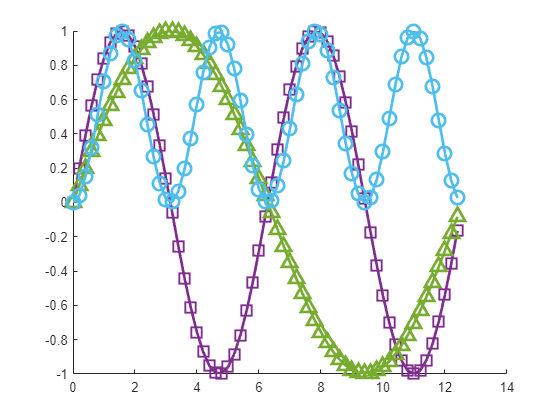


x=0:.2:4*pi;

hold on
tc={'LineWidth',2,'MarkerSize',10};

plot(x,sin(x),'-s',tc{:});
plot(x,sin(0.5.*x),'-^',tc{:});
plot(x,sin(x).^2,'-o',tc{:});
hold off

### **预设符号变量类型**

假设我们编写了如下代码：

syms x
f=x^3+x^2+9*x+9;
solve(f==0)

$$ans = \left(\begin{array}{c} -1\\ -3\,\mathrm{i}\\ 3\,\mathrm{i} \end{array}\right)$$

但如果在求解前预设x为实数：

syms x
assume(x,'real')
f=x^3+x^2+9*x+9;
solve(f==0)

$$ans = -1$$

### 巧用eval

C=cell(2,3);
C{1,1}='one';C{1,2}='two';C{1,3}='three';
C{2,1}=1;C{2,2}=2;C{2,3}=3;
for i=1:3
    eval([eval(['C{1,' num2str(i) '}']),'=C{2,' num2str(i) '};']);
end

### **进制相互转换**

就是先转成十进制，再转换为其他进制：

% 12进制转16进制
bs1=12;
bs2=16;
% 原字符
baseStr='1B';

% 转换
decStr=base2dec(baseStr,bs1);
result=dec2base(decStr,bs2)

result = '17'

因此有更简单的RGB颜色、16进制码相互转换函数:

**RGB值转16进制码函数：**

hex=RGB2HEX([251,255,250])

hex = '#FBFFFA'

**16进制码转RGB值函数：**

rgb=HEX2RGB('#FBFFFA')

rgb =    251   255   250


## **函数**

### **拟合曲线后转换成匿名函数**

x=[2 2.5 3 3.5 4 4.5 5 5.5 6];
y=[41 38 34 32 29 28 25 22 20];
p=polyfit(x,y,3);
f=matlabFunction(poly2sym(p))

xx=2:.1:6;
plot(xx,f(xx),'LineWidth',2)
grid on

### **查看每个模块包含的函数**

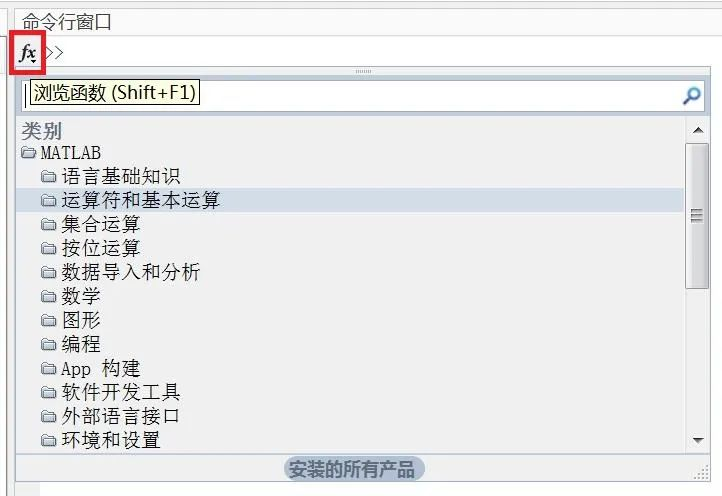

## 编辑

### 生成latex及mathml公式

**latex公式生成**

syms x
S = [sym(1)/3 x; exp(x) x^2]

$$S = \left(\begin{array}{cc} \frac{1}{3} & x\\ {\mathrm{e}}^{x} & x^{2} \end{array}\right)$$

chr = latex(S)

chr = '\left(\begin{array}{cc} \frac{1}{3} & x\\ {\mathrm{e}}^x & x^2 \end{array}\right)'

**MathML公式生成**

可以试一下直接将MathML公式复制到非WPS的word文档，会直接生成公式，不过MATLAB对于简单的公式，其生成的MathML可以直接在word生成公式，复杂的就别指望了。。。

syms x
f = 1/exp(x^2)

$$f = {\mathrm{e}}^{-x^{2}}$$

chr=mathml(f)

## 代码结构

### 注释

### 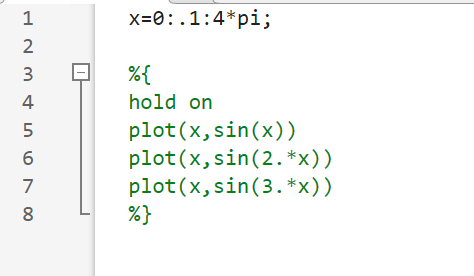

### **if 转 switch (逻辑值作为输入变量)**

假如你编写了如下代码：

score=68
if 90<=score&&score<=100
    disp('优秀');
elseif 70<=score&&score<90
    disp('良好');
elseif 60<=score&&score<70
    disp('一般');
elseif score<60
    disp('不及格');
end

有个办法能够避免大量 if else：

就是拿逻辑值作为输入使用 switch:

score=68
switch true
    case 90<=score&&score<=100
        disp('优秀');
    case 70<=score&&score<90
        disp('良好');
    case 60<=score&&score<70
        disp('一般');
    case score<60
        disp('不及格');
end

### 减少循环嵌套次数

`ind2sub`函数可以用来减少循环嵌套次数，举个简单的例子，假如编写了如下代码：

for i1=1:5
    for i2=1:3
        for i3=1:2
            disp([i1,i2,i3])
        end
    end
end

可以改写为如下代码(用处不多且需要注意顺序)：

sz=[5,3,2];
for i=1:prod(sz)
    [i3,i2,i1]=ind2sub(sz(end:-1:1),i);
    disp([i1,i2,i3])
end

### 获取工作区变量

众所周知`whos`函数可以获取当前工作区变量：

而在函数中或在app中，whos函数获取的是当前域内的变量而不是工作区变量。可以使用`evalin`函数获取指定为`base`工作区的变量：

evalin('base','whos')

function HEX=RGB2HEX(RGB)
% RGB值转16进制码函数：
    hexVec=dec2base(RGB,16)';
    HEX=['#',hexVec(:)'];
end

function RGB=HEX2RGB(HEX)
% 16进制码转RGB值函数：
    hexVec=reshape(HEX(2:end),2,[])';
    RGB=base2dec(hexVec,16)';
end